W=5

W = 5

H=3;
WHrat_trial= W/H;

WHrat_trial = 1.6667

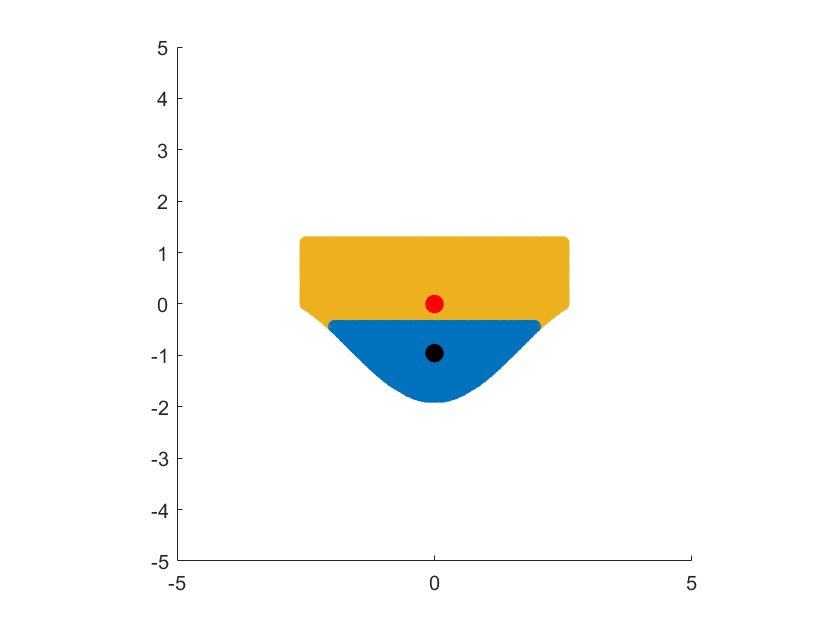

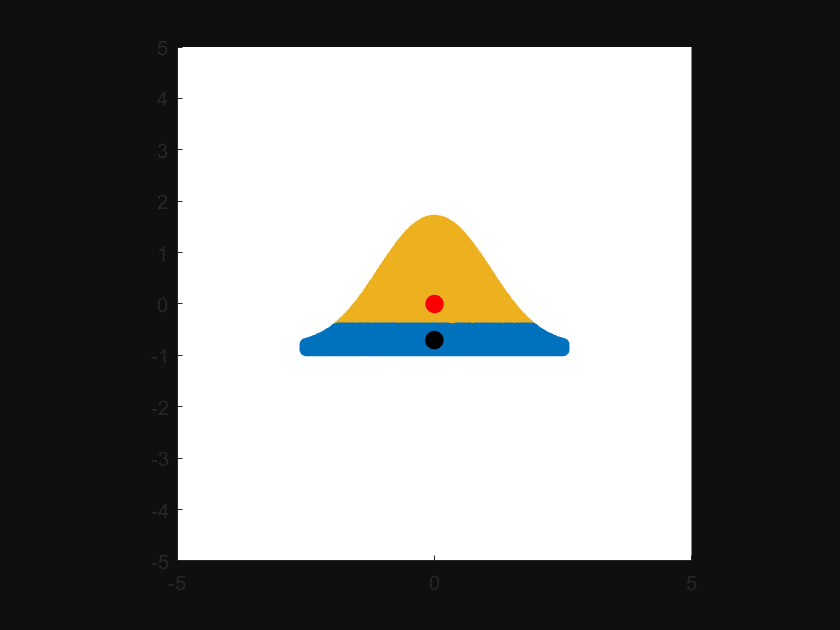

[angle, moment_arm] = boat4(W, H);

AMV_trial = amvFinder(moment_arm)
figure
plot(angle, moment_arm)

W=5

W = 5

H=3;
WHrat_trial= W/H;

WHrat_trial = 1.6667

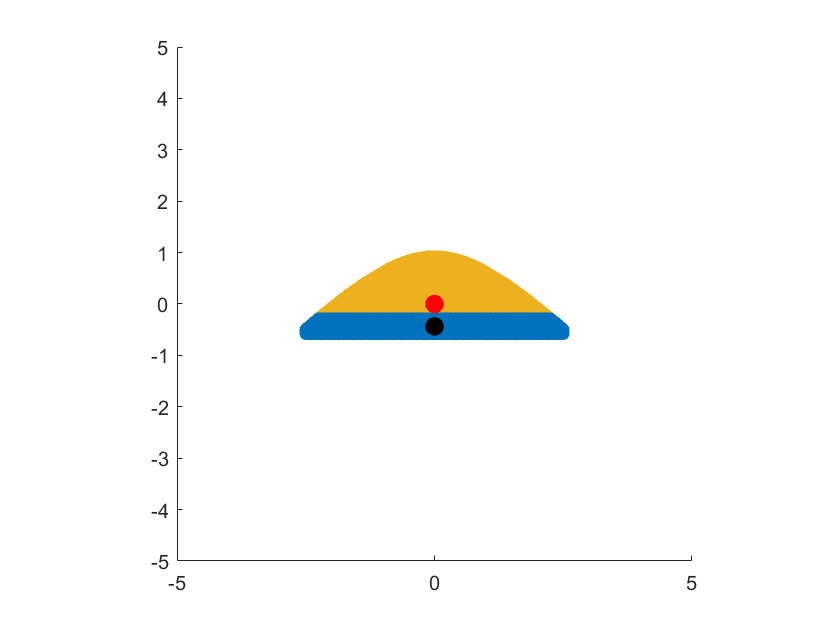

[angle, moment_arm] = goat5(W, H);

AMV_trial = amvFinder(moment_arm)

AMV_trial = 95.5000

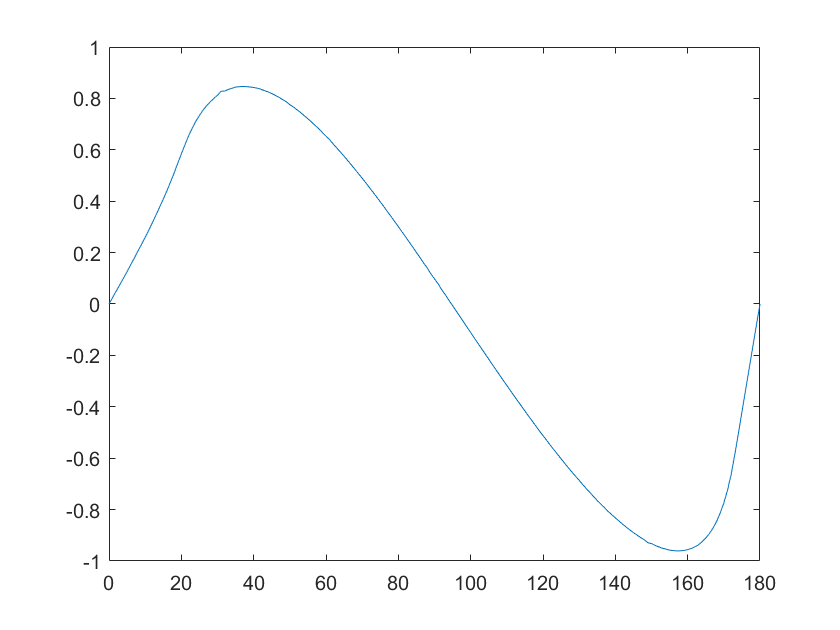

figure
plot(angle, moment_arm)

W=5

W = 5

H=3;
WHrat_trial= W/H;
[angle, moment_arm] = boat6(W, H);

AMV_trial = amvFinder(moment_arm)

AMV_trial = 106.5000

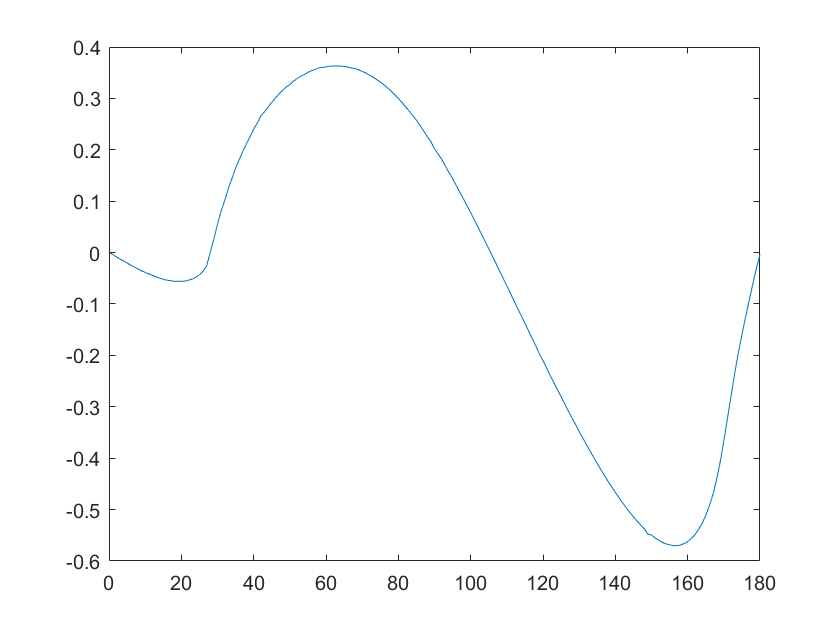

figure
plot(angle, moment_arm)

function [AMV] = amvFinder(moment_arm)
close = moment_arm(40:140);
[d ix] = min(abs(close));
val = close(ix-1:ix+1);
a1 = find(moment_arm==val(1));
a2 = find(moment_arm ==val(2));
AMV = (a1+a2)/2;
end